close all
clear all
N=100000;
x=rand(N,3)*2*pi-pi;
y=ishigamifunction(x);
fitlm(x,y)

ans = Linear regression model:
    y ~ 1 + x1 + x2 + x3

Estimated Coefficients:
                    Estimate        SE         tStat       pValue  
                   __________    _________    ________    _________

    (Intercept)        3.5094     0.010587      331.49            0
    x1                0.88879    0.0058267      152.54            0
    x2             -0.0019951    0.0058499    -0.34105      0.73306
    x3              -0.015374     0.005846     -2.6299    0.0085428


Number of observations: 100000, Error degrees of freedom: 99996
Root Mean Squared Error: 3.35
R-squared: 0.189,  Adjusted R-Squared: 0.189
F-statistic vs. constant model: 7.76e+03, p-value = 0

%%
[d,Si]=deltamim(x,y,20);
for i=1:3
    aa=corrcoef(x(:,i),y);
    rho(i)=aa(1,2);
end
subplot(2,1,1)
bar(rho);
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
set(gca,'Fontsize',24)
xticklabels(labels)
title('Pearson Correlation Coefficient')
ylabel('$\rho(Y,X_i)$','Interpreter','latex')
subplot(2,1,2)
bar(Si);
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';
set(gca,'Fontsize',24)
xticklabels(labels)
title('First-order variance-based')
ylabel('$S(Y,X_i)$','Interpreter','latex')


%% Learning an input: conditional distribution of Y given X_i = x_i^*

% Choose which input to condition on
i_cond = 1;              % 1, 2, or 3

% Choose the value of X_i
x_cond = 0;              % for example: 0, pi/2, -pi/2, etc.

% Construct a conditional input sample
x_conditional = x;

% Replace the chosen column by the fixed value
x_conditional(:,i_cond) = x_cond;

% Recompute the model output under the condition X_i = x_i^*
y_conditional = ishigamifunction(x_conditional);

% Kernel density estimates
[f_marg, y_grid_marg] = ksdensity(y);
[f_cond, y_grid_cond] = ksdensity(y_conditional);

% Plot marginal and conditional densities
figure

plot(y_grid_marg, f_marg, 'LineWidth',2)
hold on
plot(y_grid_cond, f_cond, 'LineWidth',2)

grid on
box on

xlabel('$Y$','Interpreter','latex')
ylabel('Density','Interpreter','latex')

title(sprintf('Marginal and conditional distributions, $X_%d = %.2f$', ...
    i_cond, x_cond), ...
    'Interpreter','latex')

legend({ ...
    '$Y$', ...
    sprintf('$Y\\mid X_%d = %.2f$', i_cond, x_cond)}, ...
    'Interpreter','latex', ...
    'Location','best', ...
    'Box','off');

set(gca, ...
    'TickLabelInterpreter','latex', ...
    'FontSize',24, ...
    'LineWidth',1.2);

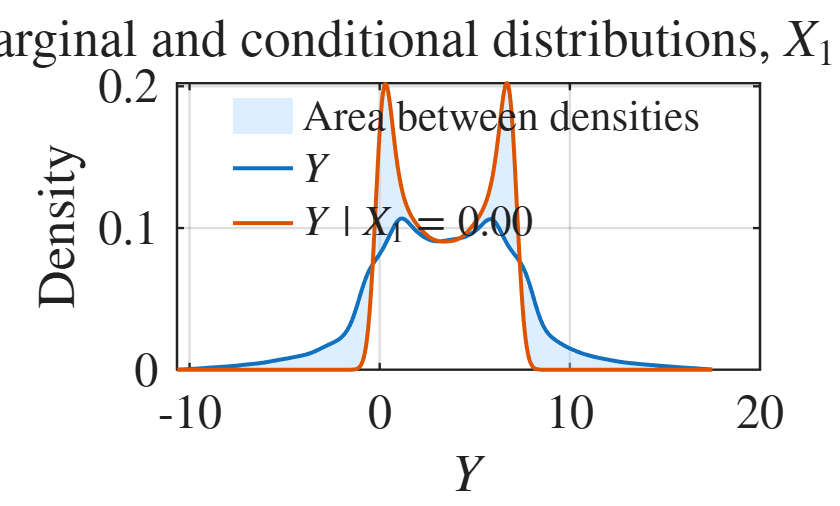


%%
%% Learning an input: conditional distribution of Y given X_i = x_i^*

% Choose which input to condition on
i_cond = 1;              % 1, 2, or 3

% Choose the value of X_i
x_cond = 0;              % for example: 0, pi/2, -pi/2, etc.

% Construct a conditional input sample
x_conditional = x;

% Replace the chosen column by the fixed value
x_conditional(:,i_cond) = x_cond;

% Recompute the model output under the condition X_i = x_i^*
y_conditional = ishigamifunction(x_conditional);

% Common grid for the two densities
y_min = min([y; y_conditional]);
y_max = max([y; y_conditional]);
y_grid = linspace(y_min, y_max, 500);

% Kernel density estimates on the same grid
f_marg = ksdensity(y, y_grid);
f_cond = ksdensity(y_conditional, y_grid);

% Plot
figure
hold on

% Light blue shaded area between the two densities
fill([y_grid fliplr(y_grid)], ...
    [f_marg fliplr(f_cond)], ...
    [0.70 0.85 1.00], ...
    'EdgeColor','none', ...
    'FaceAlpha',0.45);

% Density curves
plot(y_grid, f_marg, 'LineWidth',2)
plot(y_grid, f_cond, 'LineWidth',2)

grid on
box on

xlabel('$Y$','Interpreter','latex')
ylabel('Density','Interpreter','latex')

title(sprintf('Marginal and conditional distributions, $X_%d = %.2f$', ...
    i_cond, x_cond), ...
    'Interpreter','latex')

legend({ ...
    'Area between densities', ...
    '$Y$', ...
    sprintf('$Y\\mid X_%d = %.2f$', i_cond, x_cond)}, ...
    'Interpreter','latex', ...
    'Location','best', ...
    'Box','off');

set(gca, ...
    'TickLabelInterpreter','latex', ...
    'FontSize',24, ...
    'LineWidth',1.2);

%%
[delta,Si,acceptL,Seps]=deltamim(x,y,50,'Marginal and Conditional Densities')

delta =     0.2231    0.4074    0.1751


Si =     0.3115    0.4401    0.0004


acceptL =     1.0000    1.0000    1.0000
    1.0000    1.0000    1.0000
    1.0000    1.0000    0.9799


Seps =     0.3799    0.3690    0.3585    0.3805    0.3706    0.3999    0.4400    0.4704    0.5013    0.5269    0.5351    0.5271    0.5822    0.5483    0.5201    0.5650    0.4878    0.4764    0.4663    0.4003    0.3759    0.3464    0.3594    0.3782    0.3761    0.3793    0.3594    0.3489    0.3595    0.3673    0.3890    0.4609    0.4650    0.5144    0.5589    0.5079    0.5923    0.5485    0.5561    0.5343    0.5477    0.5337    0.4668    0.4303    0.3927    0.3773    0.3603    0.3727    0.3657    0.3812
    0.9758    0.9495    0.8860    0.7437    0.6495    0.6680    0.6936    0.6336    0.7172    0.7983    0.9051    0.9655    1.0244    0.9796    0.8965    0.8112    0.7042    0.6998    0.6703    0.6755    0.6898    0.7675    0.8754    0.9439    0.9841    0.9911    0.9410    0.8699    0.7647    0.6588    0.6674    0.6907    0.6486    0.7014    0.8154    0.9212    1.0020    0.9907    0.9831    0.9290    0.8124    0.7035    0.6738    0.7044    0.6647    0.6779    0.7685    0.9007    0.9635  

%%
figure
bar(d);
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';

xticklabels(labels)
ylabel('$\delta(Y,X_i)$','Interpreter','latex')
title('Moment independent')
set(gca,'Fontsize',24)

%%
[W,d,nn]=wassersi(x,y,50);
figure
C=W.W22/(2*var(y));
bar(W.W22/(2*var(y)))
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';

xticklabels(labels)
ylabel('$\iota(Y,X_i)$','Interpreter','latex')
title('OT-based')
set(gca,'Fontsize',24)


%%
[Wass2,WassSep,SinkSep,Mean2Sep]=bwsi(x,y,50);
%%
WB=mean(WassSep)./(2*var(y));
V2=mean(Mean2Sep)./(2*var(y));
A=[V2; WB; C];
figure
bar(A')


%%
figure
A=[V2; WB; C];
figure
b=bar(A')

b =   1×3 Bar array:

    Bar    Bar    Bar


%b.FaceColor = 'flat';
cols = [
    0.0000 0.2000 0.8000   % stronger blue
    1.0000 0.0000 0.0000   % true red
    1.0000 0.8000 0.0000   % shiny yellow
    ];

for k = 1:numel(b)
    b(k).FaceColor = cols(k,:);
end

legend({'$S(Y,X_i)$','$WB(Y,X_i)$','$\iota(Y,X_i)$'}, ...
    'Interpreter','latex', ...
    'Location','best', ...
    'Box','off','FontSize',28);
labels={'$X_1$','$X_2$','$X_3$'}

labels = 1×3 cell array
    {'$X_1$'}    {'$X_2$'}    {'$X_3$'}


ax = gca;
ax.XAxis.TickLabelInterpreter = 'latex';

xticklabels(labels)
ylabel('Importance','Interpreter','latex')
set(gca,'FontSize',28)